# **FDS 2024: Field and service robotics**

## `Homework 1 Question 5 `

## Andrea Morghen

First of all lets define the matrix map and plot it.

**This must be performed regardless of whether the 4-square or 8-square agorithm is used**

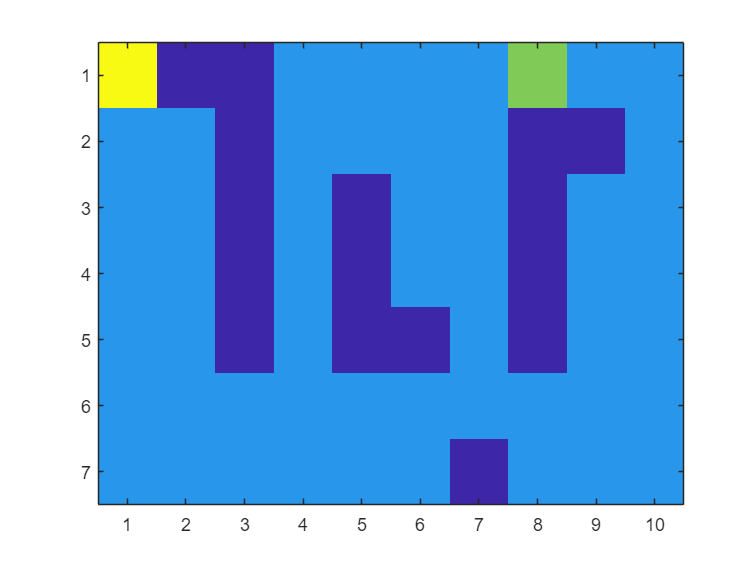

map=[3 0 0 1 1 1 1 2 1 1
     1 1 0 1 1 1 1 0 0 1
     1 1 0 1 0 1 1 0 1 1
     1 1 0 1 0 1 1 0 1 1
     1 1 0 1 0 0 1 0 1 1
     1 1 1 1 1 1 1 1 1 1
     1 1 1 1 1 1 0 1 1 1];

imagesc(map)

## Algoritm with 4 adiacent square

The algoritm ends when either the count variable currente_step reaches its maximum value max_step, either the evaluation is completed. If the the first event occuors the maz_step must be incremented before  moving on to solve the exercise.

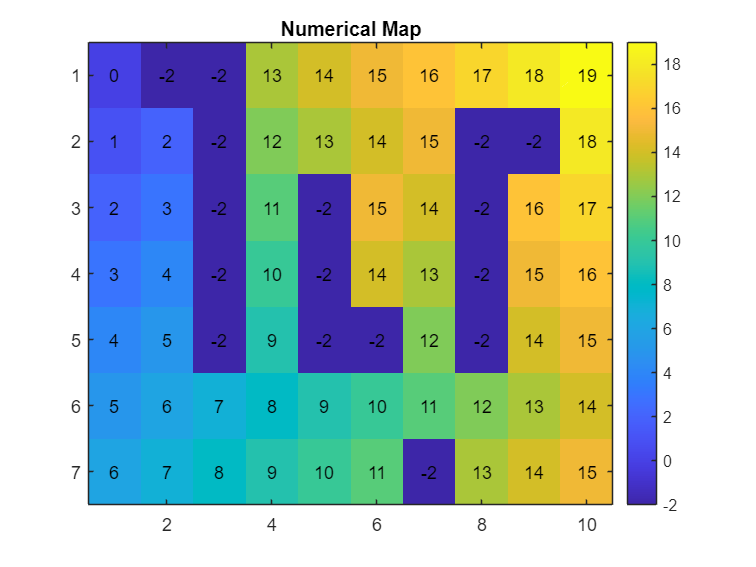

completed = false;
numerical_map= map -2*ones(size(map,1),size(map,2)); % matrix that will contain the number from the algoritm, it is inizialized in such a way that the obstacle are -2, the free path are -1 
numerical_map(find(map==3)) = 0; % in the matrix the starting point is set to 0
numerical_map(find(map==2)) = -1; % in the matrix the final point is set to -1, ther same as a free path
current_step = 0;
max_step = 30; % maximum step before stopping, security reason

while (completed == false && current_step<max_step)

    [current_positions_r,current_positions_c] = find(numerical_map==current_step); % find every map point that has a value equal to the current step 
    current_positions=[current_positions_r,current_positions_c];

    current_step=current_step+1;

    % For each point found lets check if the point up, down, left, right is a feasible point, if it isn't already numbered lets number it 
    for i=1:size(current_positions,1)
        up=current_positions(i,:)+[-1,0];
        if(up(1)>0 && up(1)<=7 && up(2)>0 && up(2)<=10)
            if(map(up(1),up(2)) ~= 0 && numerical_map(up(1),up(2)) ==-1)
                 numerical_map(up(1),up(2)) = current_step;
            end
        end
        right=current_positions(i,:)+[0,1];
        if(right(1)>0 && right(1)<=7 && right(2)>0 && right(2)<=10)
            if(map(right(1),right(2)) ~= 0 && numerical_map(right(1),right(2)) == -1)
                 numerical_map(right(1),right(2)) = current_step;
            end
        end
        down=current_positions(i,:)+[1,0];
        if(down(1)>0 && down(1)<=7 && down(2)>0 && down(2)<=10)
            if(map(down(1),down(2)) ~= 0 && numerical_map(down(1),down(2)) ==-1)
                 numerical_map(down(1),down(2)) = current_step;
            end
        end
        left=current_positions(i,:)+[0,-1];
        if(left(1)>0 && left(1)<=7 && left(2)>0 && left(2)<=10)
            if(map(left(1),left(2)) ~= 0 && numerical_map(left(1),left(2)) ==-1)
                 numerical_map(left(1),left(2)) = current_step;
            end
        end
    end
    
    % If the map doesn't have any free path left, the avaluation is completed
    if isempty(find(numerical_map==-1))
        completed=true;
    end
end

% Plot of the resulting map
imagesc(numerical_map);
colorbar;
title('Numerical Map');

[n_rows, n_col] = size(numerical_map);
for i = 1:n_rows
    for j = 1:n_col
        text(j, i, num2str(numerical_map(i, j)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
    end
end

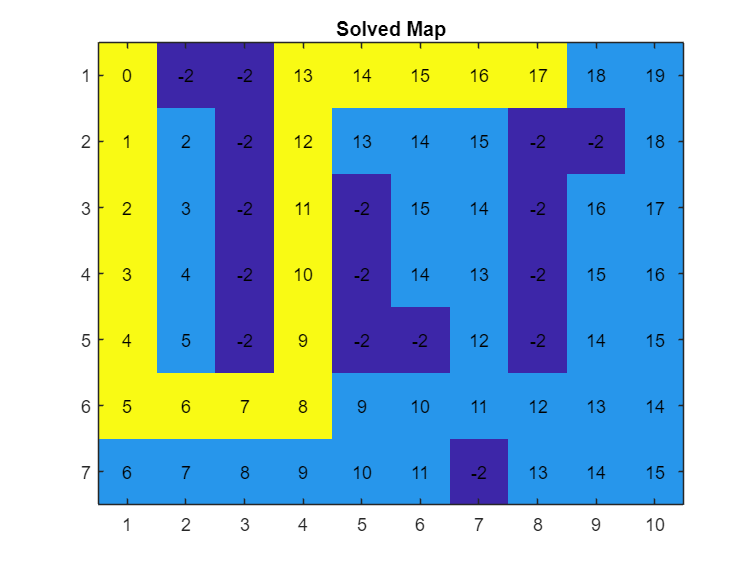

Path evaluation was completed succesfully


if completed == false
    phrase = sprintf('Map evaluation was not completed within %i iteration, please increment max_step', max_step);
    disp(phrase);
end


% If the evaluation was done right (complete evaluation of the map) we can go on by reconstruct the path from the initial point to the final goal.
[last_r,last_c] = find(map==2); % the starting pointy is extracted
last=[last_r,last_c];
path=last;

% At each iteration, the point on the map adjacent to the previous one that has a lower value than the current one is extracted
while(numerical_map(last(1),last(2))~=0 && completed == true)
    last_value = numerical_map(last(1),last(2));
    up=last+[-1,0];
    right=last+[0,1];
    down=last+[1,0];
    left=last+[0,-1];
    if(up(1)>0 && up(1)<=7 && up(2)>0 && up(2)<=10)
        if(numerical_map(up(1),up(2)) == last_value-1)
            last = up;
        end
    end
    if(right(1)>0 && right(1)<=7 && right(2)>0 && right(2)<=10)
        if(numerical_map(right(1),right(2)) == last_value-1)
            last = right;
        end
    end
    if(down(1)>0 && down(1)<=7 && down(2)>0 && down(2)<=10)
        if(numerical_map(down(1),down(2)) ==last_value-1)
            last= down;
        end
    end
    if(left(1)>0 && left(1)<=7 && left(2)>0 && left(2)<=10)
        if(numerical_map(left(1),left(2)) ==last_value-1)
            last= left;
        end
    end
    path=[path;last];
end


% Plot of the resulting map
if completed == true
    solved_map=map;  
    for i=1:length(path(:,1))
        solved_map(path(i,1),path(i,2))=3;
    end

    imagesc(solved_map);
    title('Solved Map');
   
    [n_rows, n_col] = size(solved_map);
    for i = 1:n_rows
        for j = 1:n_col
            text(j, i, num2str(numerical_map(i, j)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
        end
    end
    disp('Path evaluation was completed succesfully');
else
    disp('Map evaluation was not completed, path can not be computed');
end 

## Algoritm with 8 adiacent square

The algorithm follows the same logic as the previous one, but has been optimised by adding a for loop to reduce lines of code at the expense of a **less immediate understanding of the code**. The operation remains unchanged, the only change being that all 8 adjacent squares are now taken into account instead of 4. 

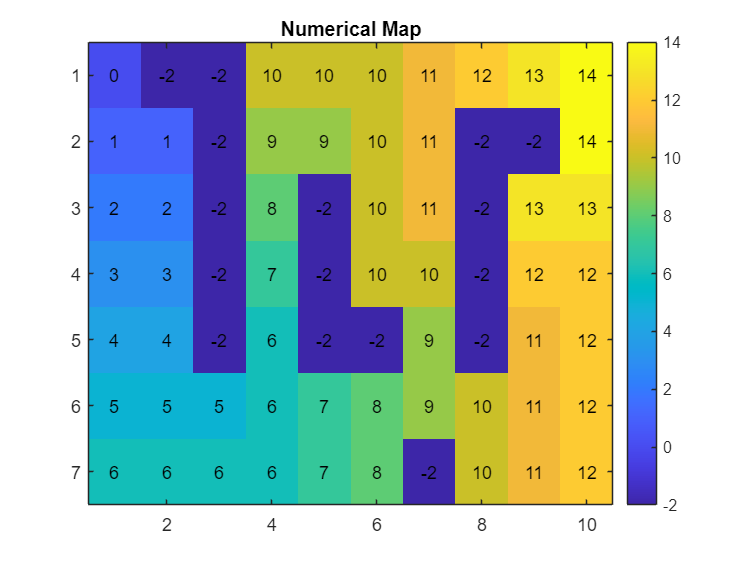

completed = false;
numerical_map= map -2*ones(size(map,1),size(map,2)); % matrix that will contain the number from the algoritm, it is inizialized in such a way that the obstacle are -2, the free path are -1 
numerical_map(find(map==3)) = 0; % in the matrix the starting point is set to 0
numerical_map(find(map==2)) = -1; % in the matrix the final point is set to -1, ther same as a free path
current_step = 0;
max_step = 30; % maximum step before stopping, security reason

while (completed == false && current_step<max_step)
    [current_positions_r,current_positions_c] = find(numerical_map==current_step); % find every map point that has a value equal to the current step 
    current_step=current_step+1;
    current_positions=[current_positions_r,current_positions_c];

    % For each point found lets check if the point up, down, left, right is a feasible point, if it isn't already numbered lets number it. 
    % This time around  the check is done using a list and a for cicle
    for i=1:length(current_positions_r+1)
        up=current_positions(i,:)+[-1,0];
        right=current_positions(i,:)+[0,1];
        down=current_positions(i,:)+[1,0];
        left=current_positions(i,:)+[0,-1];
        right_up=current_positions(i,:)+[-1,1];
        right_down=current_positions(i,:)+[1,1];
        left_down=current_positions(i,:)+[1,-1];
        left_up=current_positions(i,:)+[-1,-1];
        
        pos_dir=[right_up;right_down;left_up;left_down;up;right;down;left];

        for j=1:size(pos_dir,1)
            if(pos_dir(j,1)>0 && pos_dir(j,1)<=7 && pos_dir(j,2)>0 && pos_dir(j,2)<=10)
                if(map(pos_dir(j,1),pos_dir(j,2)) ~= 0 && numerical_map(pos_dir(j,1),pos_dir(j,2)) ==-1)
                     numerical_map(pos_dir(j,1),pos_dir(j,2)) = current_step;
                end
            end
        end
    end

    % If the map doesn't have any free path left, the avaluation is completed
    if isempty(find(numerical_map==-1))
        completed=true;
    end
end

% Plot of the resulting map
imagesc(numerical_map);
colorbar; 
title('Numerical Map');

[n_rows, n_col] = size(numerical_map);
for i = 1:n_rows
    for j = 1:n_col
        text(j, i, num2str(numerical_map(i, j)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
    end
end

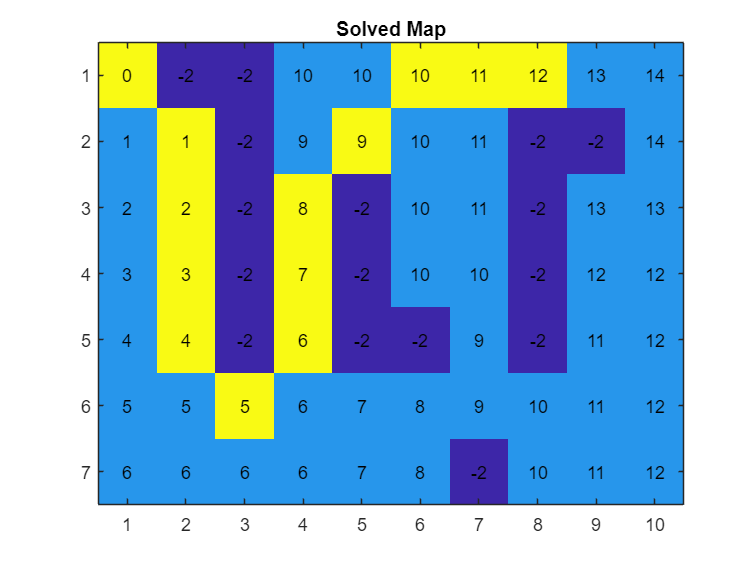

Path evaluation was completed succesfully


if completed == false
    phrase = sprintf('Map evaluation was not completed within %i iteration, please increment max_step', max_step);
    disp(phrase);
end

% If the evaluation was done right (complete evaluation of the map) we can go on by reconstruct the path from the initial point to the final goal.

[last_r,last_c] = find(map==2); % the starting pointy is extracted
last=[last_r,last_c];
path=last;

% At each iteration, the point on the map adjacent to the previous one that has a lower value than the current one is extracted
while(numerical_map(last(1),last(2))~=0)
    last_value = numerical_map(last(1),last(2));
    up=last+[-1,0];
    right=last+[0,1];
    down=last+[1,0];
    left=last+[0,-1];
    right_up=last+[-1,1];
    right_down=last+[1,1];
    left_down=last+[1,-1];
    left_up=last+[-1,-1];
     
    pos_dir=[right_up;right_down;left_up;left_down;up;right;down;left];

    for j=1:size(pos_dir,1)
        if(pos_dir(j,1)>0 && pos_dir(j,1)<=7 && pos_dir(j,2)>0 && pos_dir(j,2)<=10)
            if(numerical_map(pos_dir(j,1),pos_dir(j,2)) == last_value-1)
                 last= pos_dir(j,:);
            end
        end
    end
    path=[path;last];
end

% Plot of the resulting map
if completed == true
    solved_map=map;  
    for i=1:length(path(:,1))
        solved_map(path(i,1),path(i,2))=3;
    end

    imagesc(solved_map);
    title('Solved Map');
   
    [n_rows, n_col] = size(solved_map);
    for i = 1:n_rows
        for j = 1:n_col
            text(j, i, num2str(numerical_map(i, j)), 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle');
        end
    end
    disp('Path evaluation was completed succesfully');
else
    disp('Map evaluation was not completed, path can not be computed');
end 